# 11/22 homework

R11528052 蔡承翰

利用top-hat filter的結果與bottom-hat的結果相減來得到加強的邊緣後與原本的影像相加，之後再做watershed就能得到比較好的分割。

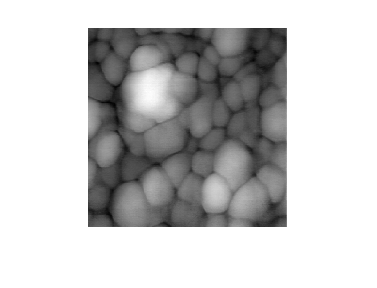

afm = imread("afmsurf.tif");
figure; imshow(afm);

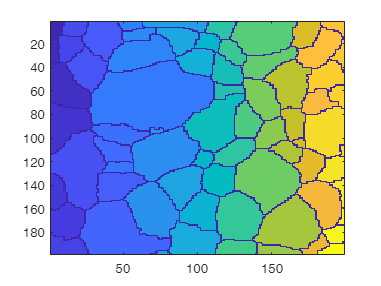

se = strel('disk', 15);

top = imtophat(afm, se);
bot = imbothat(afm, se);
lenhance = afm + top - bot;
figure; imagesc(lenhance);

lec = imcomplement(lenhance);
lemin = imextendedmin(lec, 22);
limpose = imimposemin(lec, lemin);
wat = watershed(limpose);
figure; imagesc(wat);